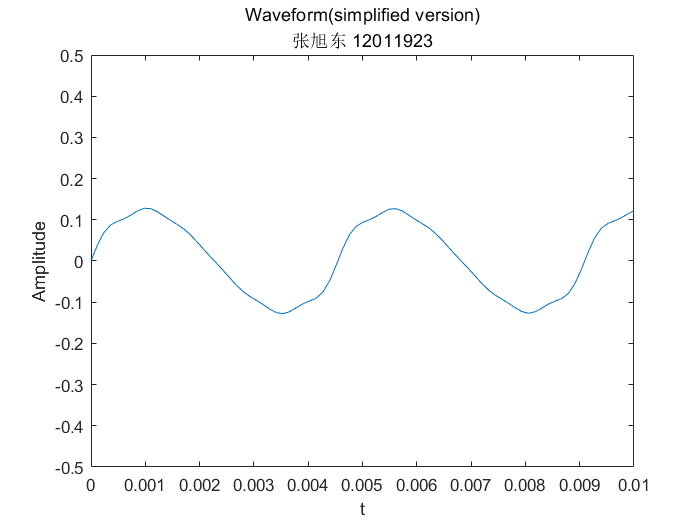

fs=8192;%采样率
fc=220;%基频
rhythm=1;%时宽
n=fs*rhythm;%采样点个数
t=linspace(0,rhythm,fs*rhythm);
f=linspace(-fs/2,fs/2-1,n);
k1=[0.1262 0.0152 0.0062 0.0044 0.0059 0.0043 0];
k2=[0.044 0.081 0.017 0.009 0.006 0.007 0.013];
y1=0;
y2=0;
for i =1:length(k1)
    y1=y1+k1(i)*sin(2*pi*i*fc*t).*exp(-2*t/rhythm);
    y2=y2+k2(i)*sin(2*pi*i*fc*t).*exp(-2*t/rhythm);
end
plot(t,y1);
xlabel('t');
ylabel('Amplitude')
title(['Waveform(simplified version)' newline '张旭东 12011923'])
axis([0 0.01 -0.5 0.5]);

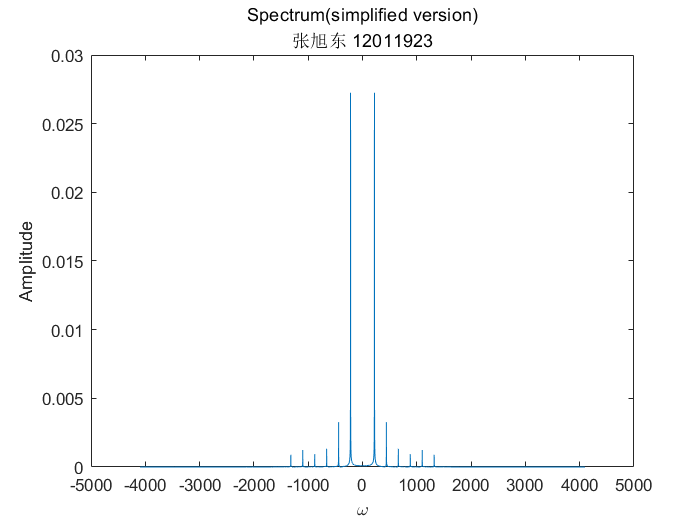

plot(f,abs(fftshift(fft(y1./n))));
xlabel('\omega');
ylabel('Amplitude')
title(['Spectrum(simplified version)' newline '张旭东 12011923'])

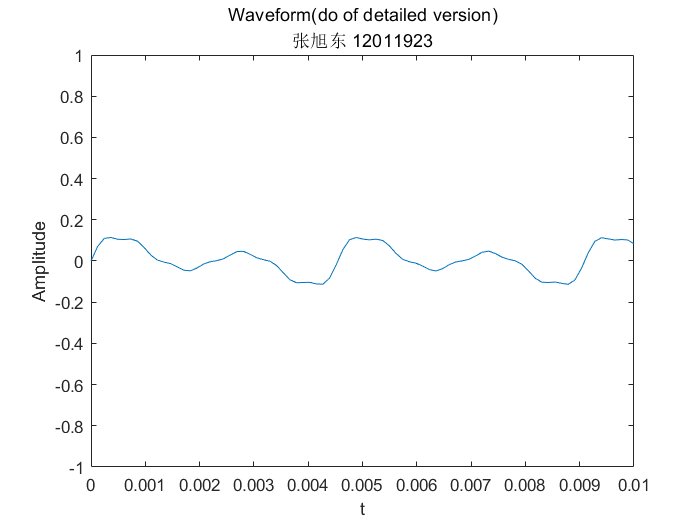

plot(t,y2);
xlabel('t');
ylabel('Amplitude')
title(['Waveform(do of detailed version)' newline '张旭东 12011923'])
axis([0 0.01 -1 1]);

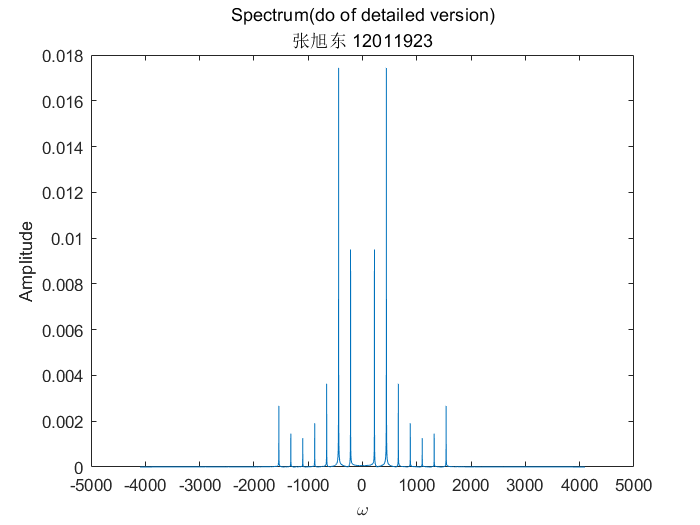

plot(f,abs(fftshift(fft(y2./n))));
xlabel('\omega');
ylabel('Amplitude')
title(['Spectrum(do of detailed version)' newline '张旭东 12011923'])


sound(y1,fs);
pause(1.5);
sound(y2,fs);